Canal 1 - mão esquerda

Canal 2 - braço esquerdo

Canal 3 - mão direita

Cnal 4 - braço direito

Leitura de dados

dados = readmatrix("Ct1_AB.txt");

Canal 1 - 1º minuto

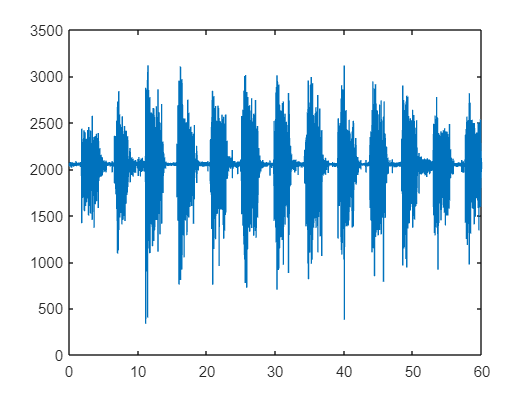

i_end = 423970; % total amostras
ch1 = dados(:, 2);
ch1_line = ch1';
fs = 1000;
s = 60;
N = fs*s;
ch1_seconds = ch1(1:N);
t = 1/fs:1/fs:s;

figure;
plot(t, ch1_seconds);

Resto dos canais

ch2 = dados(:, 3);
ch2_line = ch2';
ch2_seconds = ch2(1:N);

ch3 = dados(:, 4);
ch3_line = ch3';
ch3_seconds = ch3(1:N);

ch4 = dados(:, 5);
ch4_line = ch4';
ch4_seconds = ch4(1:N);

Plot dos 4 canais

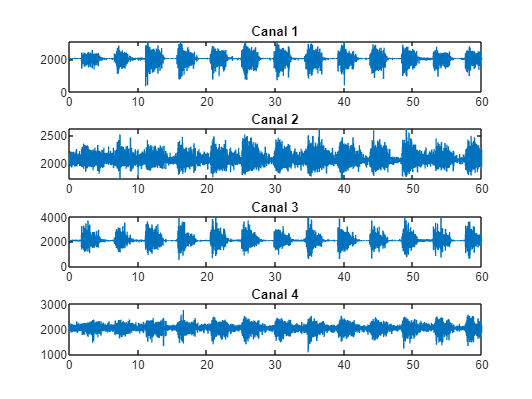

figure('Name', '4 canais');
subplot(4,1,1)
plot(t, ch1_seconds)
title('Canal 1')
subplot(4,1,2)
plot(t, ch2_seconds)
title('Canal 2')
subplot(4,1,3)
plot(t, ch3_seconds)
title('Canal 3')
subplot(4,1,4)
plot(t, ch4_seconds)
title('Canal 4')

Baseline canal 1

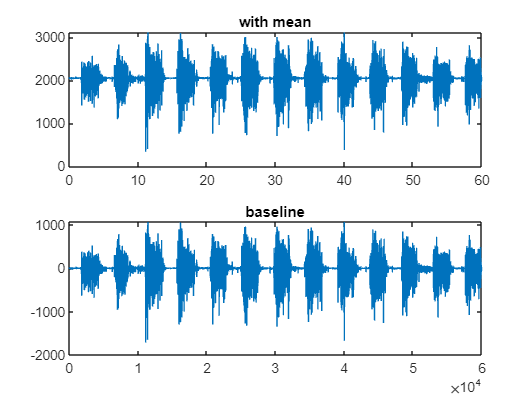

mean_ch1 = mean(ch1_seconds);
ch1_sub_mean = ch1_seconds - mean_ch1;

figure;
subplot(2,1,1);
plot(t, ch1_seconds)
title('with mean');
subplot(2,1,2);
plot(ch1_sub_mean)
title('baseline');

 Square

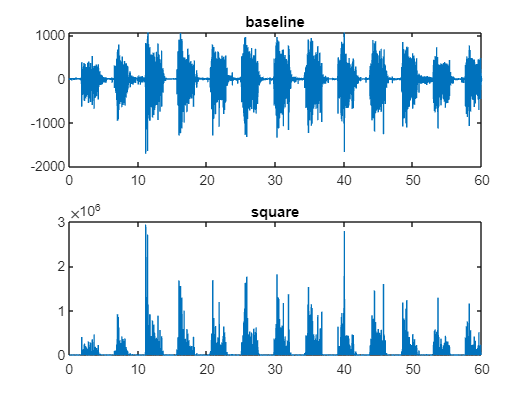

ch1_sq = (ch1_sub_mean).^2;
figure;
subplot(2, 1, 1);
plot(t, ch1_sub_mean)
title('baseline');
subplot(2, 1, 2)
plot(t, ch1_sq) 
title('square')

Envelope

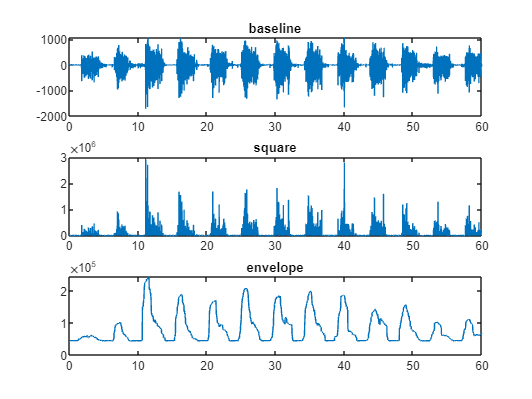

[yupper, ylower] = envelope(ch1_sq, 1000, 'rms'); % wl ?

figure('Name', 'Channel 1 - Ct1');
subplot(3, 1, 1);
plot(t, ch1_sub_mean)
title('baseline');
subplot(3, 1, 2)
plot(t, ch1_sq) 
title('square')
subplot(3, 1, 3)
plot(t,yupper)
title('envelope');

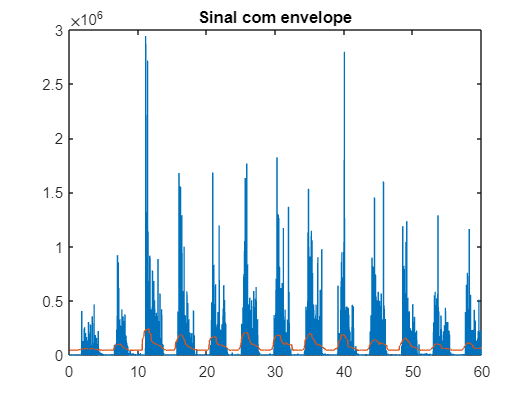


% graficos sobrepostos
figure;
plot(t, ch1_sq)
hold on
plot(t, yupper)
title('Sinal com envelope');

Limiar

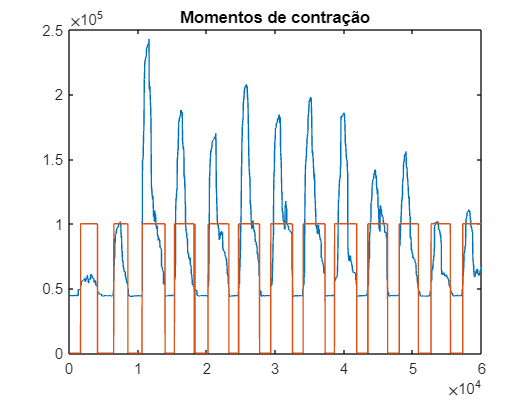

th = 50000;
indices = zeros(size(yupper));
for i= 1:length(yupper)
    if yupper(i) > th
        indices(i) = 1;
    end
end

figure;
plot(yupper)
hold on
plot(indices*100000)
title('Momentos de contração');

%xline(indices, 'red')

Conversão para mV

A expressão para transformar os dados fornecidos em mV é: 

EMG(mV) = ((x/2^n - 0,5)*Vcc)/1000

Onde x é o valor em bruto; n o número de bits = 12 e Vcc = 5.

n = 12; % n de bits
vcc = 5;

% ecg_conv = []; nao e o mais optimizavel, ja sei o tamanho da matriz
emg_conv = zeros(size(yupper)); % cria matriz de zeros

channels = [2 3 4 5];
% para cada i vou converter o sinal em mV
for i = channels % i = 1:3
    %disp(i)
    emg_conv(:,i) = emg_to_mV(yupper(:,1), n, vcc);
end

% filter designer

Espetro de potência dos 4 canais

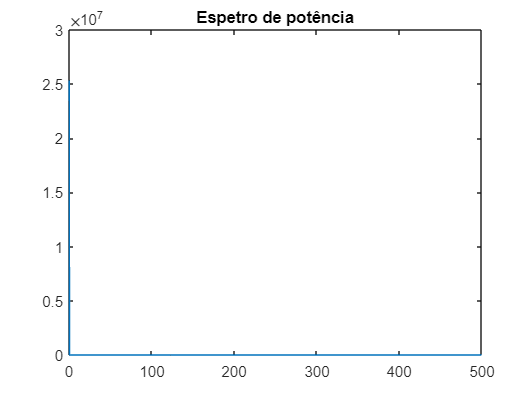

%% ver escalas
[P1, F1] = pwelch(ch1_seconds, 8192, 1024, [], fs);
%[P2, F2] = pwelch(ch2_seconds, 8192, 1024, [], fs);
%[P3, F3] = pwelch(ch3_seconds, 8192, 1024, [], fs);
figure;
plot(F1,P1)
%hold on
%plot(F2,P2)
%hold on
%plot(F3,P3)
title('Espetro de potência')

Derivada

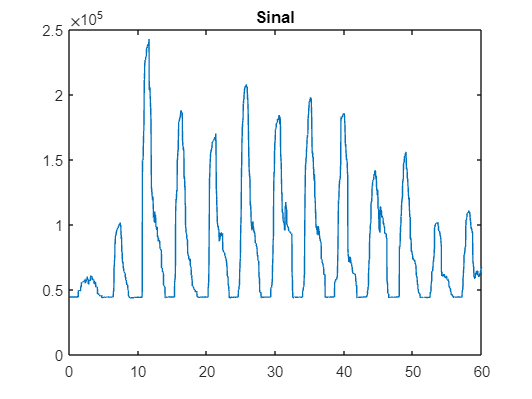

ch1_diff = diff(yupper);
figure;
plot(t, yupper);
title('Sinal');

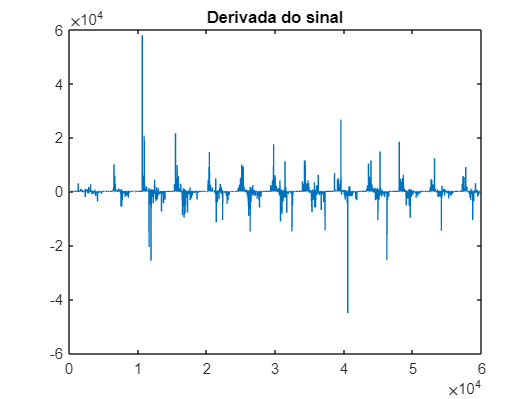


% reajustar tempo para vetor do diff
t_diff = 1/fs:2/fs:s;


figure;
plot(ch1_diff)
title('Derivada do sinal');

Correlação

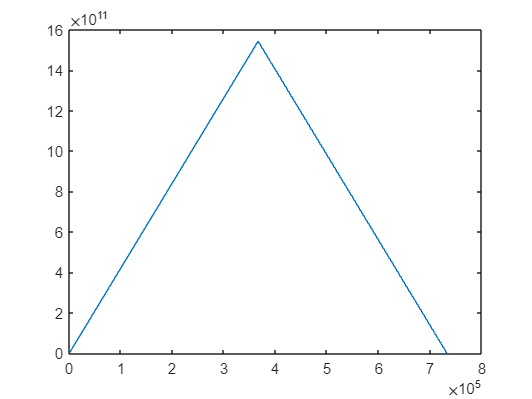

c = xcorr2(ch1_line, ch2_line);
figure;
plot(c)

Nota: normalizar